# Class 6 Homework - Xinyi (Cynthia) Shen

## Problem

Using the PDE method, price the same KO option as we had in class, but use today’s option values, implied volatilities, etc.

### Get Stock Price, Call and Pot Option Prices, Implied Volatilities for KO

After October 25, 2024, Friday market closes, I got a snap of the December 20, 2024 call and put option straddle for the Coca-Cola company (KO) on Yahoo! Finance.

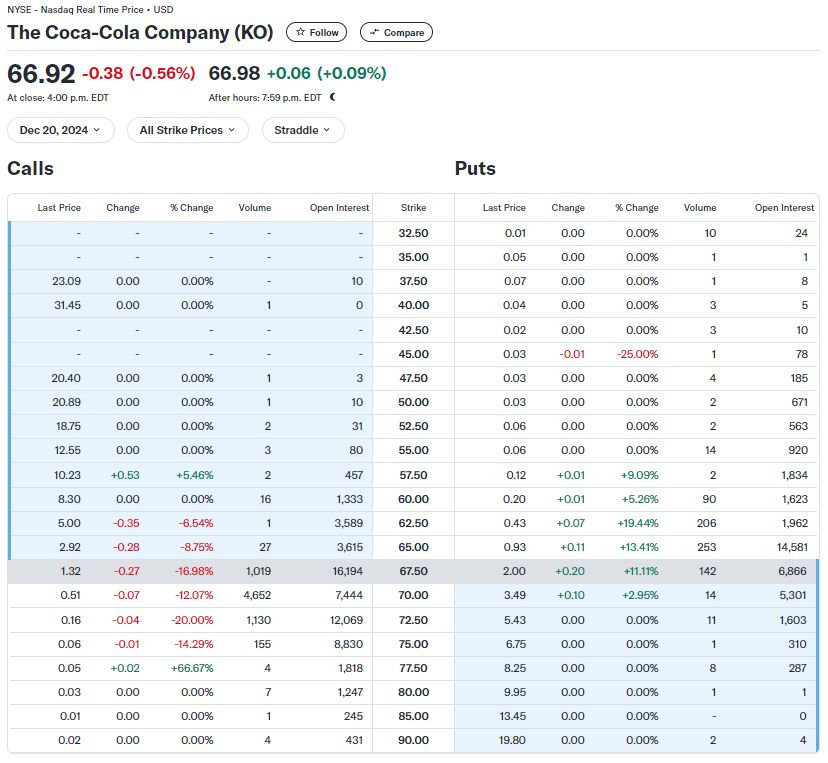

At the market close of 4:00 PM EDT, KO's price was given as $66.92. We will focus on the $67.50 dollar level for the homework.

K = 67.5;
C_MKT = 1.32;
P_MKT = 2;

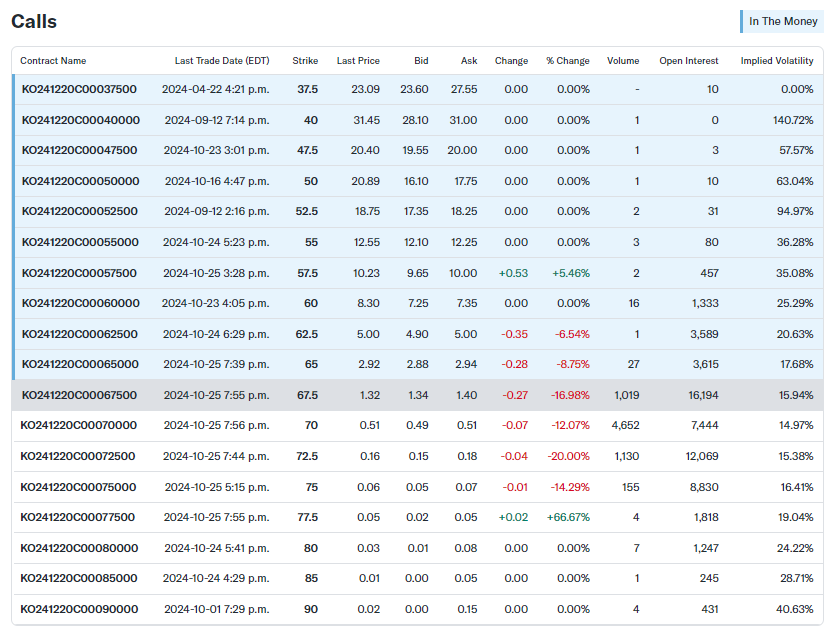

 The implied volatility for the $67.5 strike call was 15.94%

sigma67p5Call = 0.1594;

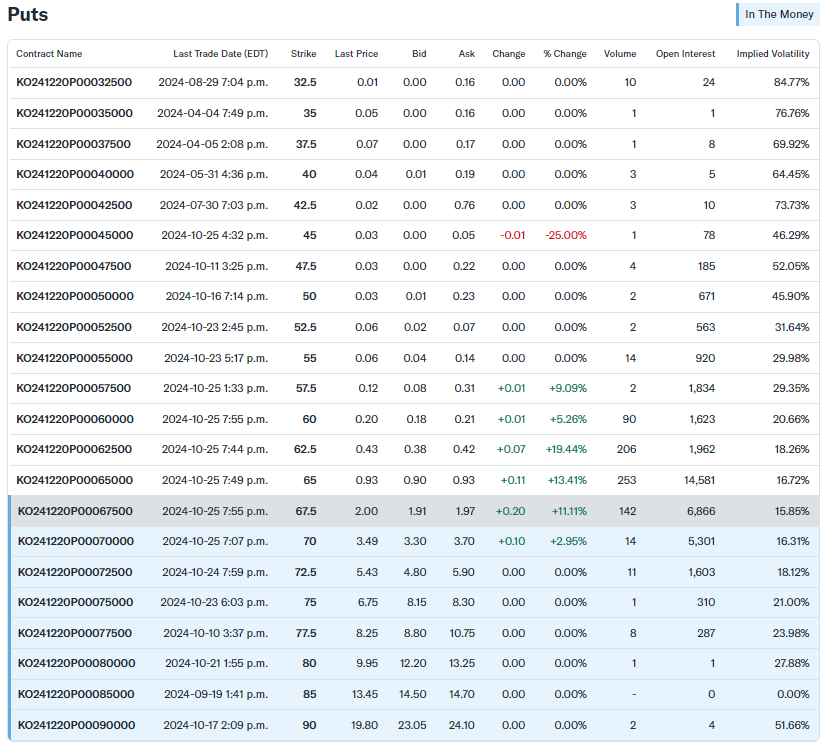

The implied volatility for the $67.5 strike put was 15.85%.

sigma67p5Put = 0.1585;

SOFR Rate:

% Given SOFR 180-day average
SOFR_180_day = 0.053009; % 5.3009% as a decimal

% Annualize the rate with semi-annual compounding
r = (1 + SOFR_180_day / 2)^2 - 1

r = 0.0537

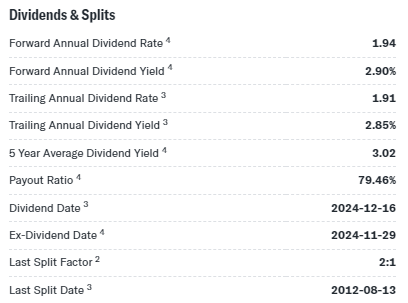

The trailing annual dividend yield is 2.85%.

q = 0.0285;
b = r - q

b = 0.0252

For December 20, 2024 we calculate T in years

To = datenum(2024,10,25);
TExpiration = datenum(2024,12,20);
TDays = (TExpiration - To); % in days
T = (TExpiration - To) / 365 % in years

T = 0.1534

### Download Historical Stock Data for KO

% Download data for Coke
startDate = '2019-10-25';
endDate = '2024-10-26';
KO_data = py.yfinance.download('KO', pyargs('start', startDate, 'end', endDate, 'interval', '1d'));


[*********************100%***********************]  1 of 1 completed


TTKO = table(KO_data);
TTKO = renamevars(TTKO, ["Adj Close"], ["Price"]);
TTKO = removevars(TTKO,["Open","High","Low","Close","Volume"])

TTKO = 1259×2 table
       Date        Price 
    ___________    ______

    25-Oct-2019    46.038
    28-Oct-2019    45.884
    29-Oct-2019    45.747
    30-Oct-2019    46.201
    31-Oct-2019     46.62
    01-Nov-2019    46.167
    04-Nov-2019    45.516
    05-Nov-2019    44.899
    06-Nov-2019    45.224
    07-Nov-2019    44.787
    08-Nov-2019    44.719
    11-Nov-2019    44.402
    12-Nov-2019    44.291
    13-Nov-2019     44.89
    14-Nov-2019    45.079
    15-Nov-2019    45.113


% What is the historical volatility of the stock over different time frames
tHistorical = datenum(TTKO.Date);
SHistorical = TTKO.Price;
So = SHistorical(end)

So = 66.9200

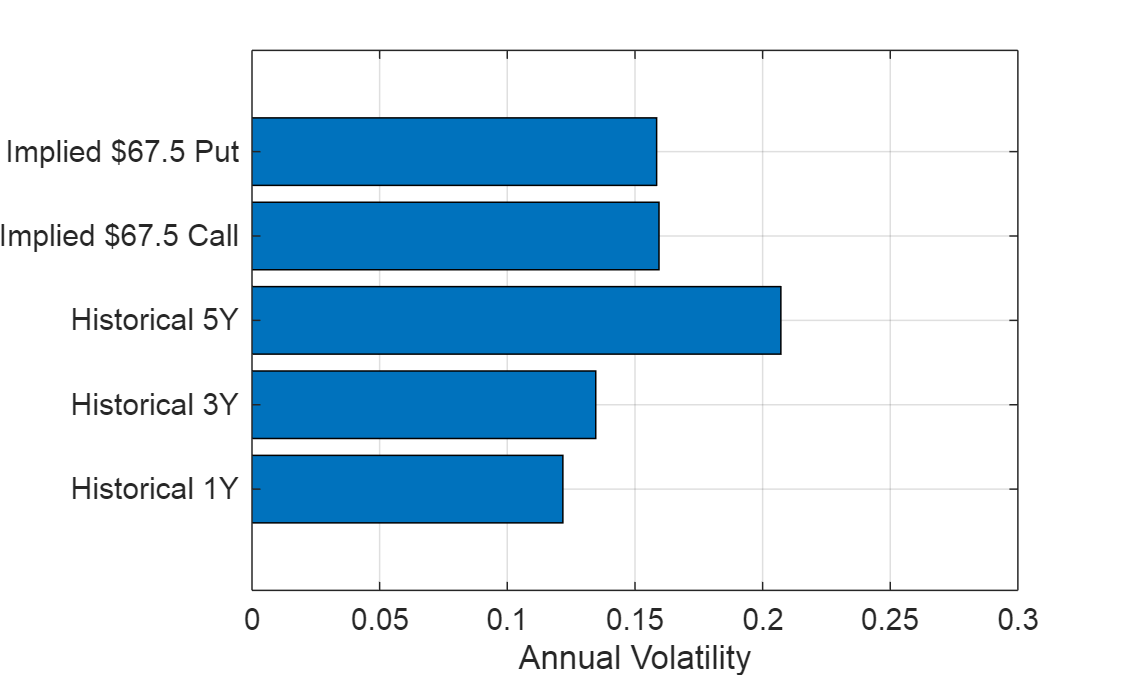

rKO = diff(SHistorical) ./ SHistorical(1:end-1);
 
sigmaHist1YEAR = std(rKO(end-252+1:end)) * sqrt(252);
sigmaHist3YEAR = std(rKO(end-2*252+1:end)) * sqrt(252);
sigmaHist5YEAR = std(rKO(1:end)) * sqrt(252);

% Results and Output
figure()
set(gcf,'Position',[0,0,500,300])
 
barh([sigmaHist1YEAR, sigmaHist3YEAR, sigmaHist5YEAR, sigma67p5Call, sigma67p5Put])
 
xlabel('Annual Volatility')
set(gca,'YTickLabels', {'Historical 1Y', ...
                        'Historical 3Y', ...
                        'Historical 5Y',... 
                        'Implied $67.5 Call', ...
                        'Implied $67.5 Put'})
xlim([0 0.3])
box on
grid on

### Use PDE to Price KO American Call Option as of December 20, 2024

#### (1) Construct Grid of Prices, Times, etc.

% The Grid
SMin = K/2;
SMax = K*2;
 
XMin = log(SMin/So);
XMax = log(SMax/So);
NX = 300;

% The 1+return vector
XGridPDE = linspace(XMin, XMax, NX)';
dX = (XMax - XMin) / NX;

% The Stock Price vector
SGridPDE = So * exp(XGridPDE);

% The Time vector
TMin = 0;
TMax = T;
NT = 1000;
 
dT = (TMax - TMin) / NT;
TGridPDE = linspace(TMin, TMax, NT);

#### (2) Define Option Value V(S,t)

% Option Value
IntrinsicVPDE = max(SGridPDE - K, 0);
VPDE = NaN(NX, NT);

#### (3) Define Binary Conditions

% Boundary Conditions
% at expiration
VPDE(:,end) = max(SGridPDE - K, 0);
 
% at the boundary SMax
VPDE(end,:) = max(SGridPDE(end) - K, 0);
 
% at the boundary SMin
VPDE(1,:) = max(SGridPDE(1) - K, 0);

#### (4) Define Key Calculation Terms

% Key Calculations
pu = (sigma67p5Call^2 * dT) / (2 * dX^2) + (b - sigma67p5Call^2/2) * dT / (2*dX);
pm = 1 - sigma67p5Call^2 * dT / (dX^2);
pd = (sigma67p5Call^2 * dT) / (2 * dX^2) - (b - sigma67p5Call^2/2) * dT / (2*dX);

#### (5) Backward PDE Algorithm

% Adjust the PDE loop for American option
for n = (NT-1):-1:1
    for j = 2:NX-1
        VPDE(j,n) = max(IntrinsicVPDE(j), (pu * VPDE(j+1,n+1) + pm * VPDE(j,n+1) + pd * VPDE(j-1,n+1)) / (1 + r*dT));
    end
end
ICurrentPrice = find(SGridPDE >= So, 1, 'first');
C_PDE_AMER = VPDE(ICurrentPrice:ICurrentPrice);
formatted_price = sprintf('American Call Option Price using PDE: $%.2f', C_PDE_AMER);
disp(formatted_price);

American Call Option Price using PDE: $1.57


#### (6) Results and Graphs

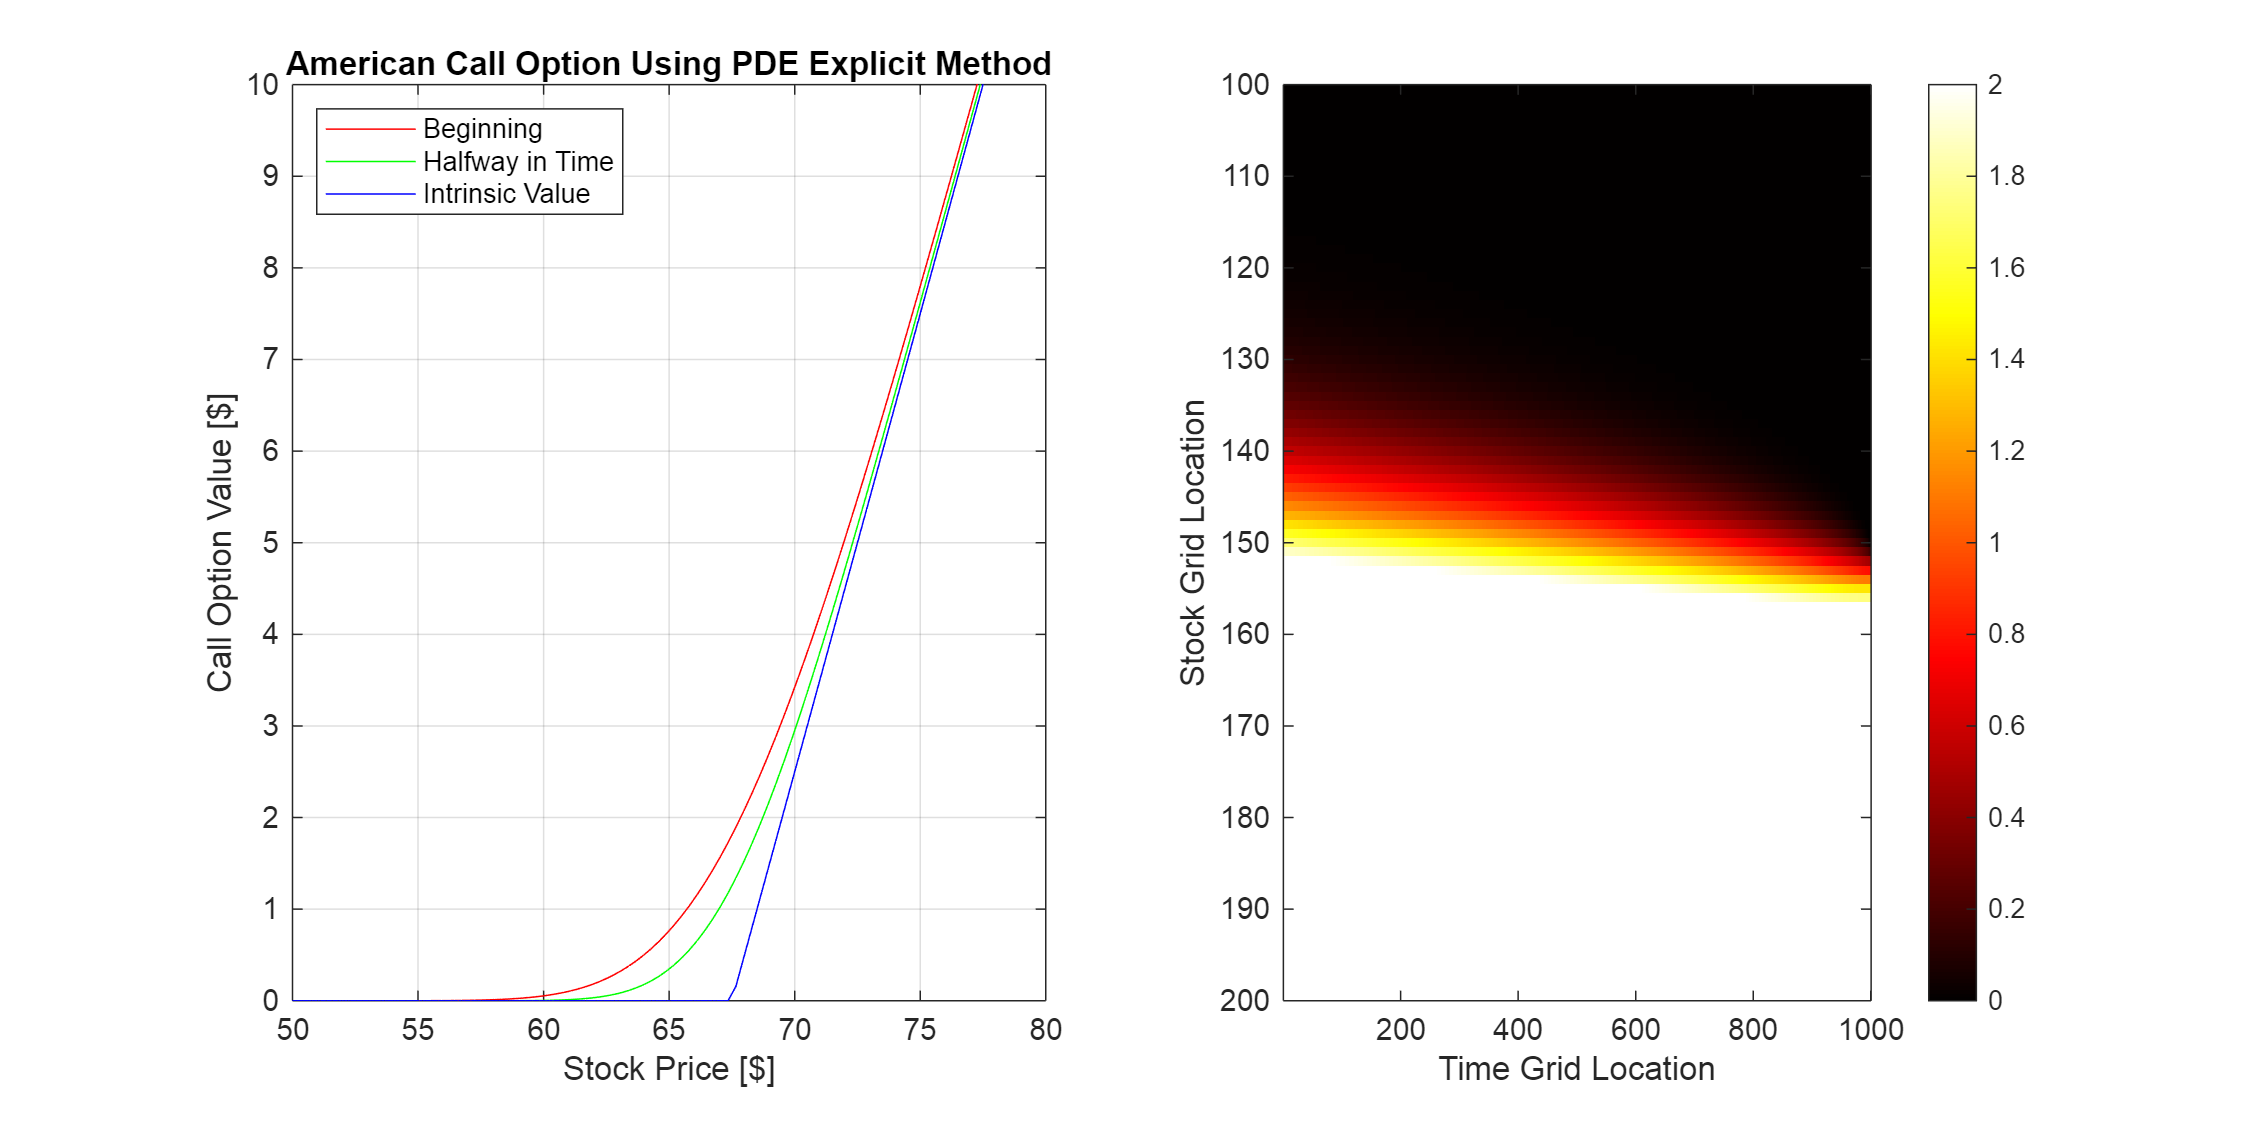

figure()
set(gcf,'Position',[0,0,1000,500])
 
subplot(1,2,1)
plot(SGridPDE, VPDE(:,1), 'r-', SGridPDE, VPDE(:,round(NT/2)), 'g-', SGridPDE, VPDE(:,NT), 'b-')
 
xlabel('Stock Price [$]')
ylabel('Call Option Value [$]')
title('American Call Option Using PDE Explicit Method')
legend({'Beginning','Halfway in Time', 'Intrinsic Value'}, 'location', 'northwest')
 
grid on
xlim([50 80])
ylim([0 10])
 
subplot(1,2,2)
%imagesc(SGridPDE, TGridPDE, VPDE)
imagesc(VPDE)
 
xlabel('Time Grid Location')
ylabel('Stock Grid Location')
colormap(hot)
ylim([100,200])
%xlim([50,100])
caxis([0,2])
colorbar

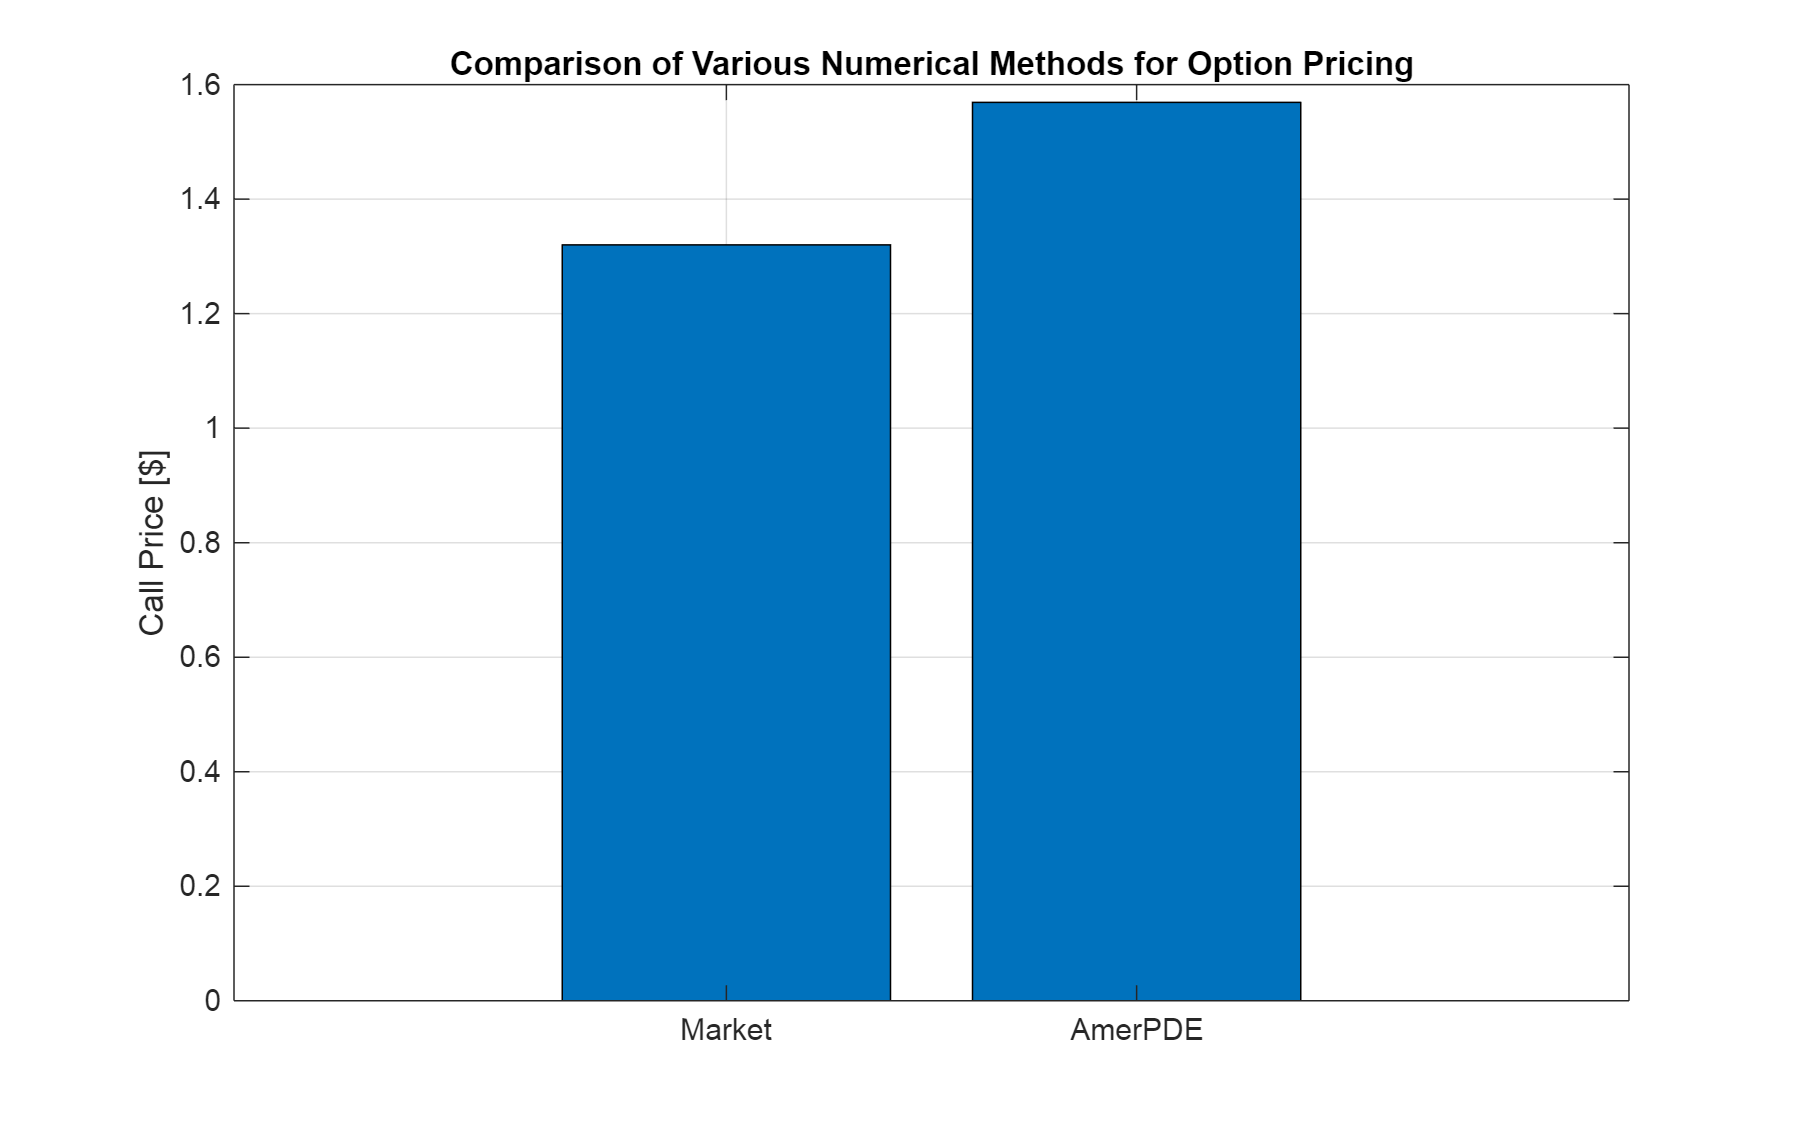

% Update on call option price by various methods
figure()
 
set(gcf,'Position',[0,0,800,500])
 
bar([C_MKT, C_PDE_AMER])
title('Comparison of Various Numerical Methods for Option Pricing')
ylabel('Call Price [$]')
set(gca, 'XTickLabels', {'Market', 'AmerPDE'})
 
box on
grid on